clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, %%legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultlegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

alfa = [0,1,3]; 
CM = [4,2,1];

[cMslope,zeroangle_moment,zeromoment_angle,xMpts,MomentCurve,MomentR2] = GetMoment(alfa,CM)

cMslope = -0.9286

zeroangle_moment = 3.5714

zeromoment_angle = 3.8462

xMpts =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5152    0.5455    0.5758    0.6061    0.6364    0.6667    0.6970    0.7273    0.7576    0.7879    0.8182    0.8485    0.8788    0.9091    0.9394    0.9697    1.0000    1.0303    1.0606    1.0909    1.1212    1.1515    1.1818    1.2121    1.2424    1.2727    1.3030    1.3333    1.3636    1.3939    1.4242    1.4545    1.4848


MomentCurve =     3.5714    3.5433    3.5152    3.4870    3.4589    3.4307    3.4026    3.3745    3.3463    3.3182    3.2900    3.2619    3.2338    3.2056    3.1775    3.1494    3.1212    3.0931    3.0649    3.0368    3.0087    2.9805    2.9524    2.9242    2.8961    2.8680    2.8398    2.8117    2.7835    2.7554    2.7273    2.6991    2.6710    2.6429    2.6147    2.5866    2.5584    2.5303    2.5022    2.4740    2.4459    2.4177    2.3896    2.3615    2.3333    2.3052    2.2771    2.2489    2.2208    2.1926


MomentR2 = 0.8622

cMslope

cMslope = -0.9286

zeroangle_moment

zeroangle_moment = 3.5714

zeromoment_angle

zeromoment_angle = 3.8462

MomentR2

MomentR2 = 0.8622

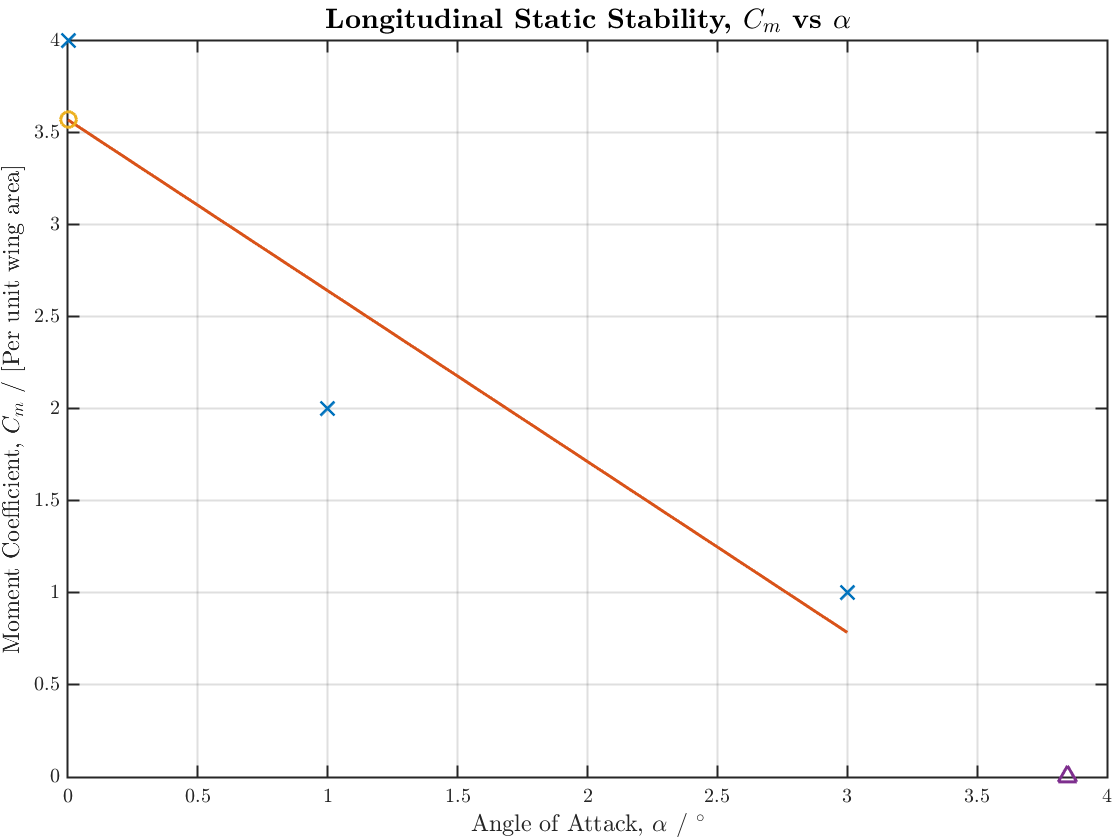

figure
hold on;
plot(alfa, CM, 'x', 'LineWidth', 1.5, 'markerSize',8);
plot(xMpts, MomentCurve, '-', 'LineWidth', 1.5, 'markerSize',8);
plot(0,zeroangle_moment, 'o', 'LineWidth', 1.5, 'markerSize',8);
plot(zeromoment_angle, 0, '^', 'LineWidth', 1.5, 'markerSize',8);
hold off
xlabel("Angle of Attack, $\alpha$ / $^{\circ}$",'FontSize',lsize)
ylabel("Moment Coefficient, $C_m$ / [Per unit wing area]",'FontSize',lsize)
title(['\textbf{Longitudinal Static Stability, $C_m$ vs $\alpha$}'],'FontSize',tsize)

box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

CL = [1,3,6]; targetCl = 2

targetCl = 2


% Now work out your needed Angle
[OutputAoA,slope,zeroangle_lift,zerolift_angle,xpts,FitCurve,AlfaR2] = GetAlfa(alfa,CL,targetCl,10)

OutputAoA = 0.5217

slope = 1.6429

zeroangle_lift = 1.1429

zerolift_angle = -0.6957

xpts =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5152    0.5455    0.5758    0.6061    0.6364    0.6667    0.6970    0.7273    0.7576    0.7879    0.8182    0.8485    0.8788    0.9091    0.9394    0.9697    1.0000    1.0303    1.0606    1.0909    1.1212    1.1515    1.1818    1.2121    1.2424    1.2727    1.3030    1.3333    1.3636    1.3939    1.4242    1.4545    1.4848


FitCurve =     1.1429    1.1926    1.2424    1.2922    1.3420    1.3918    1.4416    1.4913    1.5411    1.5909    1.6407    1.6905    1.7403    1.7900    1.8398    1.8896    1.9394    1.9892    2.0390    2.0887    2.1385    2.1883    2.2381    2.2879    2.3377    2.3874    2.4372    2.4870    2.5368    2.5866    2.6364    2.6861    2.7359    2.7857    2.8355    2.8853    2.9351    2.9848    3.0346    3.0844    3.1342    3.1840    3.2338    3.2835    3.3333    3.3831    3.4329    3.4827    3.5325    3.5823


AlfaR2 = 0.9944

slope

slope = 1.6429

zeroangle_lift

zeroangle_lift = 1.1429

zerolift_angle

zerolift_angle = -0.6957

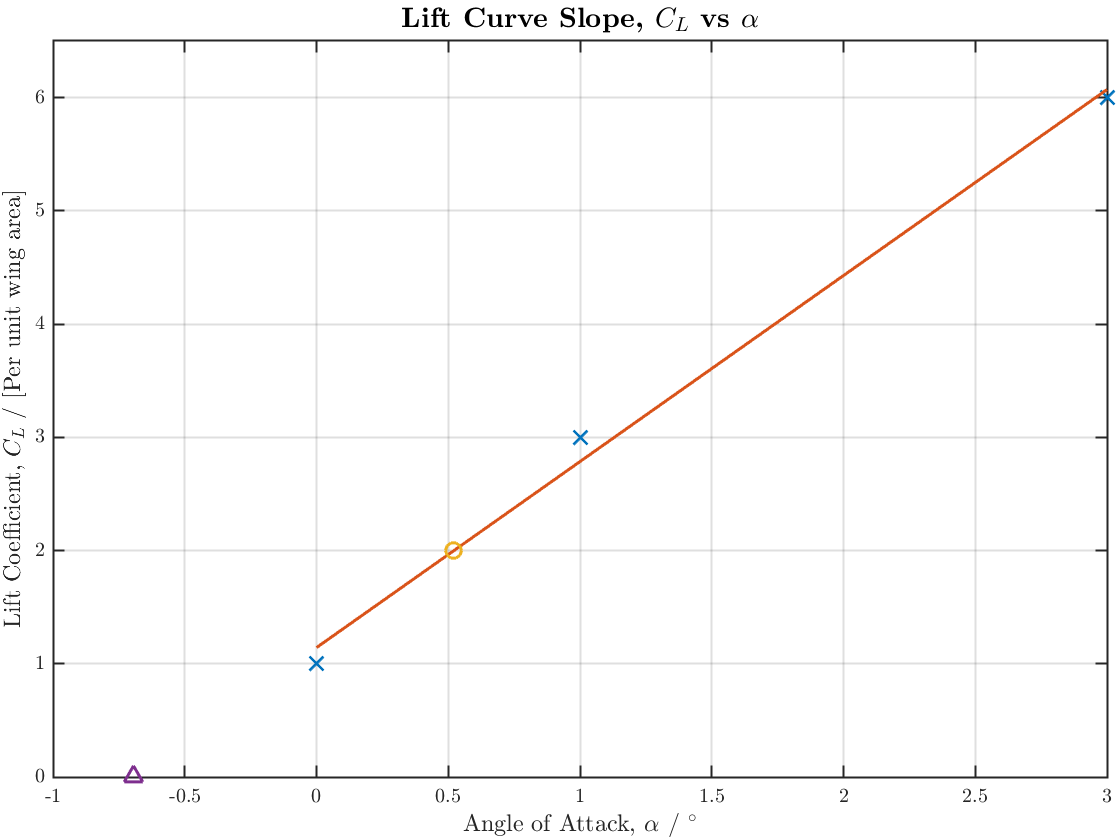

figure
hold on;
plot(alfa, CL, 'x', 'LineWidth', 1.5, 'markerSize',8);
plot(xpts, FitCurve, '-', 'LineWidth', 1.5, 'markerSize',8);
plot(OutputAoA, targetCl, 'o', 'LineWidth', 1.5, 'markerSize',8);
plot(zerolift_angle, 0, '^', 'LineWidth', 1.5, 'markerSize',8);
hold off
xlabel("Angle of Attack, $\alpha$ / $^{\circ}$",'FontSize',lsize)
ylabel("Lift Coefficient, $C_L$ / [Per unit wing area]",'FontSize',lsize)
title(['\textbf{Lift Curve Slope, $C_L$ vs $\alpha$}'],'FontSize',tsize)
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;
xlim([-1,3])
ylim([0,6.5])


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[MomentLiftSlope,zerolift_moment,zeromoment_lift,xMLpts,FitLMCurve,MomentR2_lift] = GetMoment_lift(CM,CL)

MomentLiftSlope = -0.5789

zerolift_moment = 4.2632

zeromoment_lift = 7.3636

xMLpts =     1.0000    1.0505    1.1010    1.1515    1.2020    1.2525    1.3030    1.3535    1.4040    1.4545    1.5051    1.5556    1.6061    1.6566    1.7071    1.7576    1.8081    1.8586    1.9091    1.9596    2.0101    2.0606    2.1111    2.1616    2.2121    2.2626    2.3131    2.3636    2.4141    2.4646    2.5152    2.5657    2.6162    2.6667    2.7172    2.7677    2.8182    2.8687    2.9192    2.9697    3.0202    3.0707    3.1212    3.1717    3.2222    3.2727    3.3232    3.3737    3.4242    3.4747


FitLMCurve =     3.6842    3.6550    3.6257    3.5965    3.5673    3.5380    3.5088    3.4795    3.4503    3.4211    3.3918    3.3626    3.3333    3.3041    3.2749    3.2456    3.2164    3.1871    3.1579    3.1287    3.0994    3.0702    3.0409    3.0117    2.9825    2.9532    2.9240    2.8947    2.8655    2.8363    2.8070    2.7778    2.7485    2.7193    2.6901    2.6608    2.6316    2.6023    2.5731    2.5439    2.5146    2.4854    2.4561    2.4269    2.3977    2.3684    2.3392    2.3099    2.2807    2.2515


MomentR2_lift = 0.9098

MomentLiftSlope

MomentLiftSlope = -0.5789

zerolift_moment

zerolift_moment = 4.2632

zeromoment_lift

zeromoment_lift = 7.3636

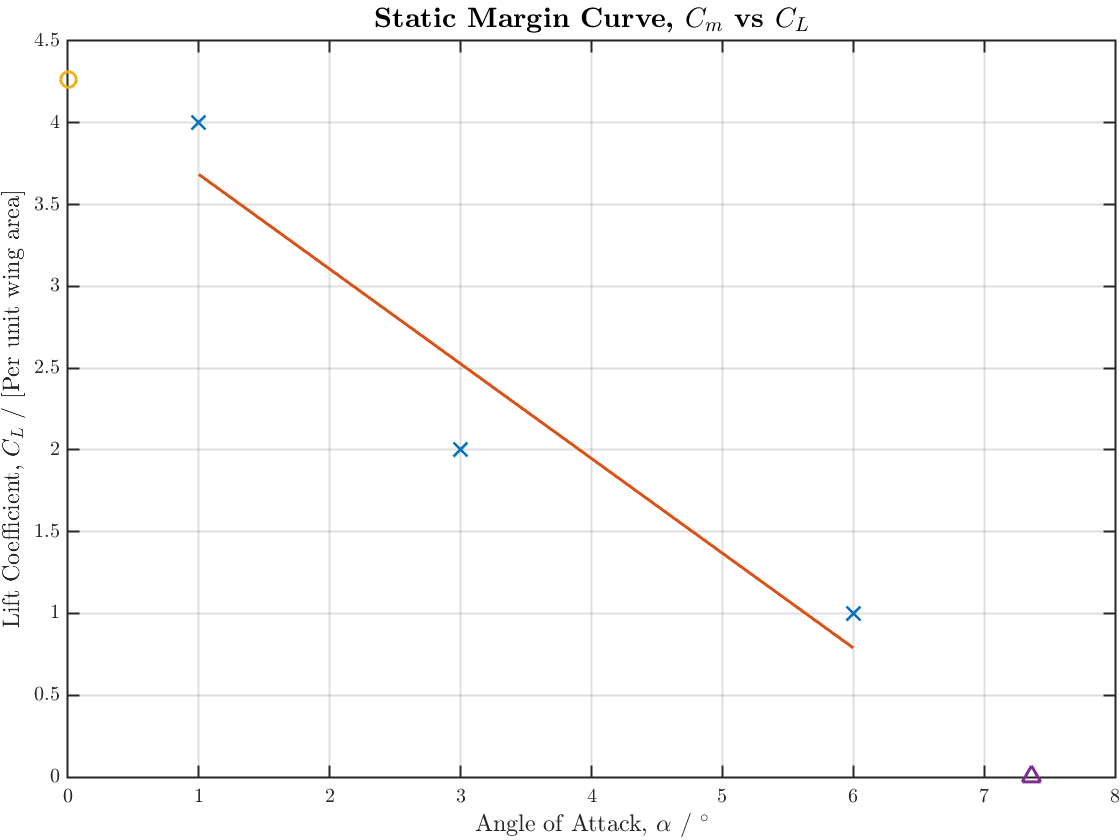

figure
hold on;
plot(CL, CM, 'x', 'LineWidth', 1.5, 'markerSize',8);
plot(xMLpts, FitLMCurve, '-', 'LineWidth', 1.5, 'markerSize',8);
plot(0,zerolift_moment, 'o', 'LineWidth', 1.5, 'markerSize',8);
plot(zeromoment_lift, 0, '^', 'LineWidth', 1.5, 'markerSize',8);
hold off
xlabel("Angle of Attack, $\alpha$ / $^{\circ}$",'FontSize',lsize)
ylabel("Lift Coefficient, $C_L$ / [Per unit wing area]",'FontSize',lsize)
title(['\textbf{Static Margin Curve, $C_m$ vs $C_L$}'],'FontSize',tsize)
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


% Stability if dCM/dCL< 0

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

CD = [0.5,1,2];
[OutputDrag,K,small,CDo,xpts,FitCurve,dragR2] = GetDrag(CL,CD,targetCl)

OutputDrag = 0.7333

K = 0.0167

small = 0.1833

CDo = 0.3000

xpts =     1.0000    1.0505    1.1010    1.1515    1.2020    1.2525    1.3030    1.3535    1.4040    1.4545    1.5051    1.5556    1.6061    1.6566    1.7071    1.7576    1.8081    1.8586    1.9091    1.9596    2.0101    2.0606    2.1111    2.1616    2.2121    2.2626    2.3131    2.3636    2.4141    2.4646    2.5152    2.5657    2.6162    2.6667    2.7172    2.7677    2.8182    2.8687    2.9192    2.9697    3.0202    3.0707    3.1212    3.1717    3.2222    3.2727    3.3232    3.3737    3.4242    3.4747


FitCurve =     0.5000    0.5110    0.5221    0.5332    0.5445    0.5558    0.5672    0.5787    0.5903    0.6019    0.6137    0.6255    0.6374    0.6494    0.6615    0.6737    0.6860    0.6983    0.7107    0.7233    0.7359    0.7485    0.7613    0.7742    0.7871    0.8001    0.8133    0.8264    0.8397    0.8531    0.8665    0.8801    0.8937    0.9074    0.9212    0.9351    0.9490    0.9631    0.9772    0.9914    1.0057    1.0201    1.0346    1.0491    1.0638    1.0785    1.0933    1.1082    1.1232    1.1383


dragR2 = 1

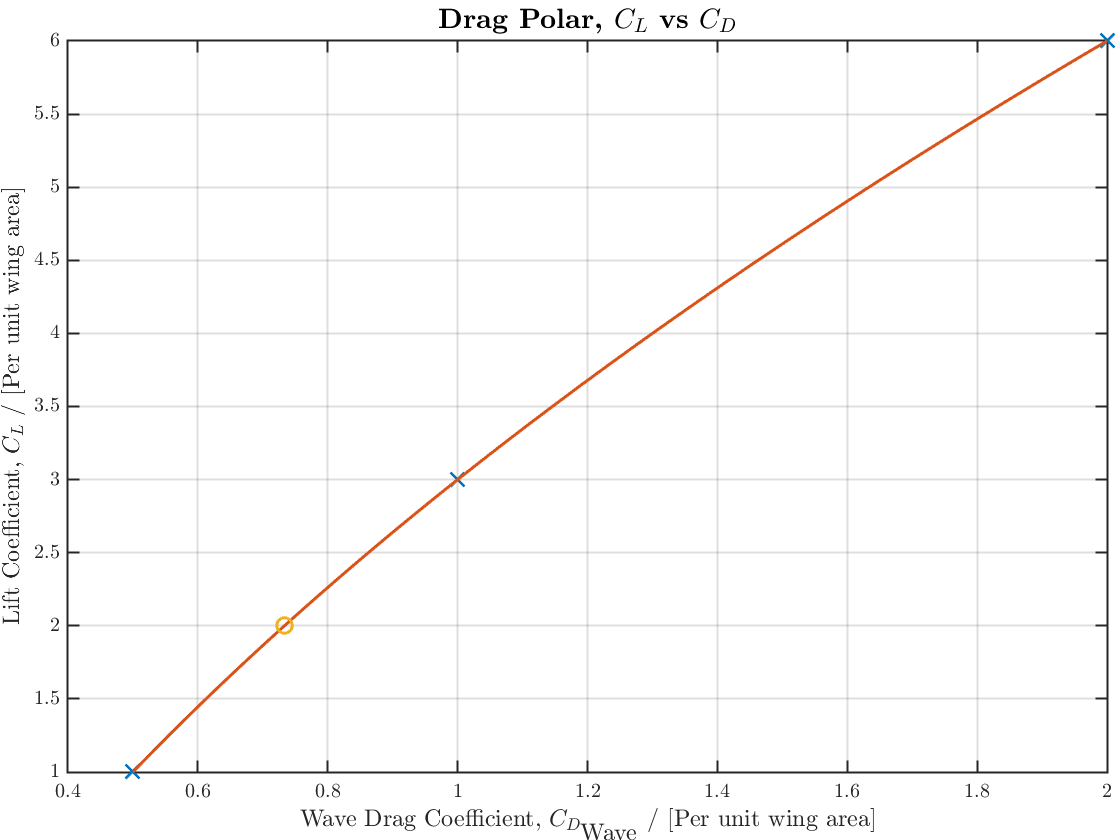


figure
hold on;
plot(CD, CL, 'x', 'LineWidth', 1.5, 'markerSize',8);
plot(FitCurve,xpts,  '-', 'LineWidth', 1.5, 'markerSize',8);
plot(OutputDrag,targetCl,'o', 'LineWidth', 1.5, 'markerSize',8);
hold off
xlabel("Wave Drag Coefficient, $C_{D_{\textrm{Wave}}}$ / [Per unit wing area]",'FontSize',lsize)
ylabel("Lift Coefficient, $C_L$ / [Per unit wing area]",'FontSize',lsize)
title(['\textbf{Drag Polar, $C_L$ vs $C_D$}'],'FontSize',tsize)
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

function r = rSquared(snorm,y)
r=1 - (snorm/norm(y - mean(y)))^2;
end

function [MomentLiftSlope,zerolift_moment,zeromoment_lift,xMLpts,MomentLiftCurve,r] = GetMoment_lift(CM,CL)
[coeffs,S] = polyfit(CL, CM, 1);
r=rSquared(S.normr,CM);
xMLpts = linspace(CL(1), CL(length(CL)), 100);
MomentLiftCurve = polyval(coeffs, xMLpts);
MomentLiftSlope=coeffs(1);
zerolift_moment=coeffs(2);
zeromoment_lift = (-coeffs(2))/coeffs(1);
end

function [cMslope,zeroangle_moment,zeromoment_angle,xMpts,MomentCurve,r] = GetMoment(alfa,CM)
[coeffs,S] = polyfit(alfa, CM, 1);
r=rSquared(S.normr,CM);
xMpts = linspace(alfa(1), alfa(length(alfa)), 100);
MomentCurve = polyval(coeffs, xMpts);
cMslope=coeffs(1);
zeroangle_moment=coeffs(2);
zeromoment_angle = (-coeffs(2))/coeffs(1);
end

function [AoA,slope,yintercept,xintercept,xFit,alfaFit,r] = GetAlfa(alfa,CL,targetCl,iters)
[coeffs,S] = polyfit(alfa, CL, 1);
r=rSquared(S.normr,CL);
xFit = linspace(alfa(1), alfa(length(alfa)), 100);
alfaFit = polyval(coeffs, xFit);
AoA(1) = fzero(@(x) polyval(coeffs, x)-(targetCl), iters);
slope=coeffs(1);
yintercept=coeffs(2);
xintercept = (-coeffs(2))/coeffs(1);
end

function [Drag,K,small,CDo,xFit2,DFit,r] = GetDrag(CL,CD,targetCl)
[Dragcoeffs,S] = polyfit(CL, CD, 2);
r=rSquared(S.normr,CL);
Drag = polyval(Dragcoeffs, targetCl);
xFit2 = linspace(CL(1), CL(length(CL)), 100);
DFit = polyval(Dragcoeffs, xFit2);
K=Dragcoeffs(1);
small=Dragcoeffs(2);
CDo=Dragcoeffs(3);
end